# 线性规划

clc, clear
f = [-20; -30; -45];
A = [4, 8, 15; 1, 1, 1;];   
b =[100 ; 20];              
lb = zeros(3, 1);          
[x, fval] = linprog(f, A, b, [], [], lb)   


Optimal solution found.



x =    15.0000
    5.0000
         0


fval = -450

y = -fval

y = 450

disp('A, B, C三图分别通关的次数为：')

A, B, C三图分别通关的次数为：


disp(x)

   15.0000
    5.0000
         0



disp('最终获得的经验为：')

最终获得的经验为：


disp(y)

   450



## 投资收益最大化问题

clc,clear;
a = [0:0.001:0.05];
f = [-0.05,-0.27,-0.19,-0.185,-0.185];
A = [zeros(4,1),diag([0.025,0.015,0.055,0.026])];   
% A是不等式约束条件的变量系数构成的矩阵
% 用zeros(4,1)先构造4行一列的全是0的矩阵，也就是x_0无约束
% 再构造对角矩阵diag([0.025,0.015,0.055,0.026]),对角线上的元素为约束条件中变量的系数
Aeq = [1,1.01,1.02,1.045,1.065];    % 等式约束的系数矩阵，也就是所有资产投资 
beq = 1;
lb = zeros(5,1);            
Q = zeros(1,length(a));     % 初始化保存最优解的矩阵Q，因为现在还没求出最优解，元素全设为0
XX = [];    % 定义个空矩阵，用来村不同风险下的最有解
% 利用矩阵Q储存风险率a(i)下最大的收益；for循环中i在变化，风险率a(i)不同，求出对应的最优解存在矩阵Q内
for i = 1:length(a)     % length求出矩阵a的元素个数，有多少个元素，就循环多少次
    b = a(i)*ones(4,1); % b是约束条件的常数项矩阵，4行1列，每个元素值都是常熟a(i)
    [x,y] = linprog(f,A,b,Aeq,beq,lb);  % 调用linprog函数
    Q(i) = -y;          % 负负得正，就是所需求的最大值了
    XX = [XX;x'];       % 
end


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal sol

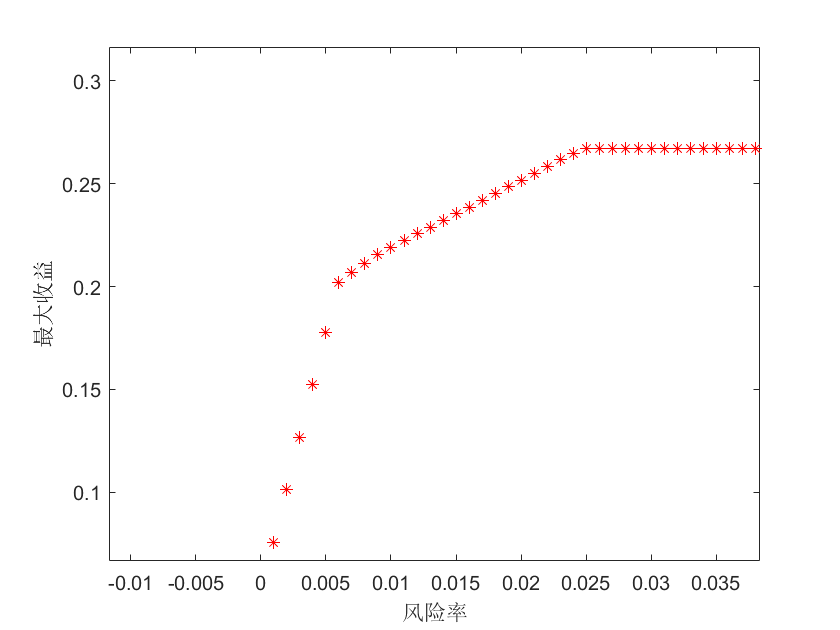

plot(a,Q,'*r');     % 以风险率为横轴，收益为纵轴，绘制不同风险率下的最优收益
xlabel('风险率');
ylabel('最大收益');